# Assignment 2

Assignment2_Curtis.mlx

#### Alex Curtis    EENG350    2/10/22

This live script contains every exercise in assignment 2. I recomend running the whole script first to initialize the workspace. Once that's done, each part can be run separately.

If you'd like to open the Simulink models instead of loading them in the background, change open_system to open_system.

## Motor Parameters

The constants used in creating the motor model

Ra = 1;     % armature resistance   [Ohms]
Kt = 0.5;   % motor torque constant [Nm/A]
Ke = 0.5;   % back emf constant     [Vs/rad]
J = 0.05;   % Load inertia          [Nm^2]
b = 0.5;    % damping               [Nm/s]

This simulation applies a rectifed sinusoidal voltage to a DC motor model, with the output as the angular position in radians.

#### Plot of Motor Output

Baseline motor response

*Requires motorsim.slx*

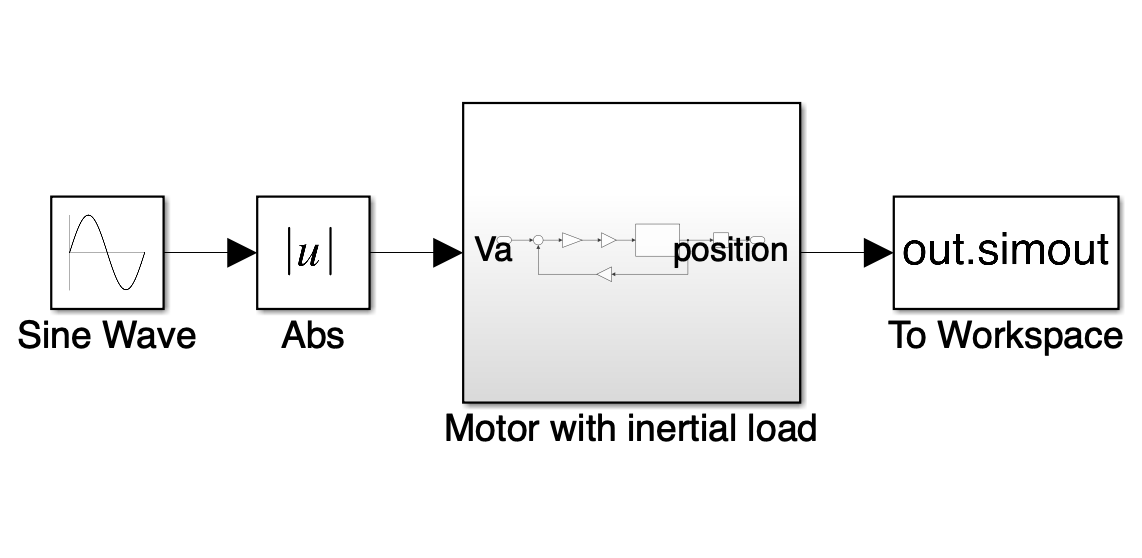

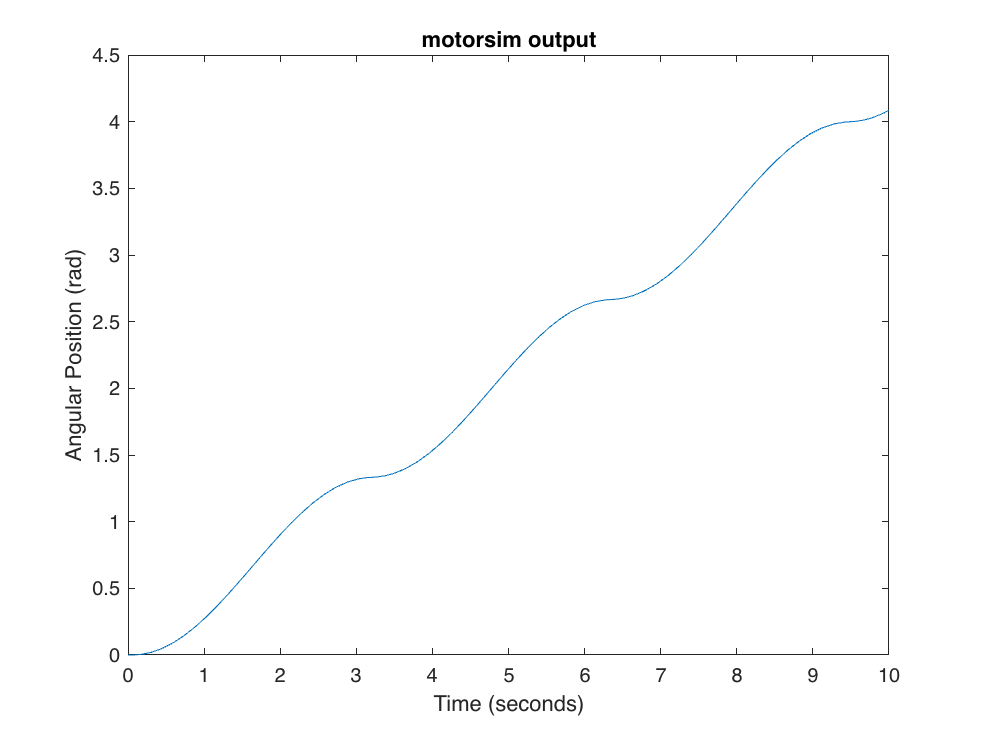

open_system('motorsim')          % Load the model
out1 = sim('motorsim');
figure                           % Create output figure
plot(out1.simout)
title('motorsim output')
ylabel('Angular Position (rad)')

The motor rotates in the positive direction, with some oscillations due to the varying input

#### Motor Response with PWM Input

Shows the effect of a continuous PWM input

*Requires motorPWM.slx*

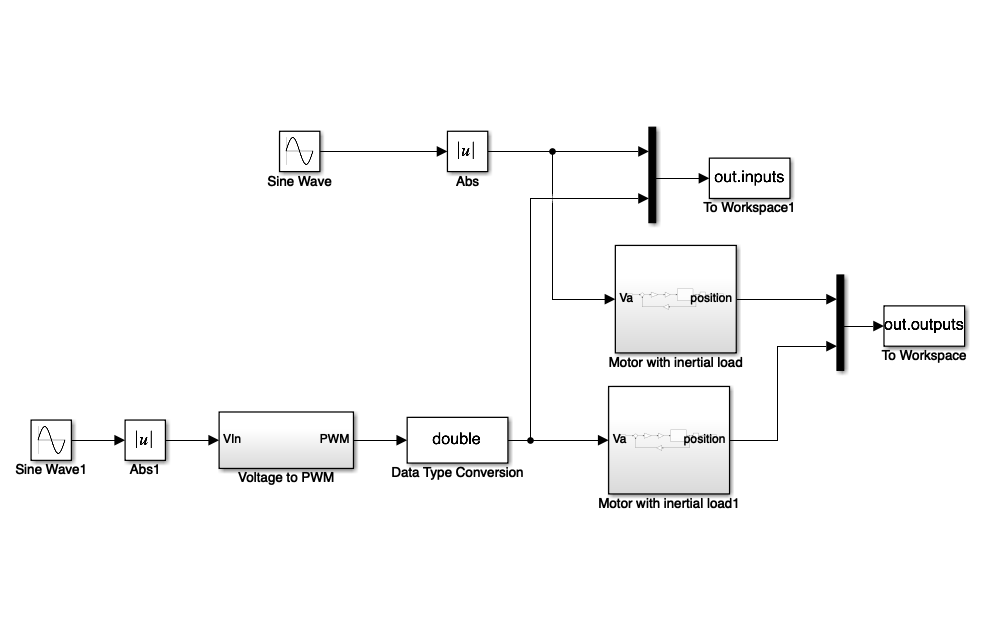

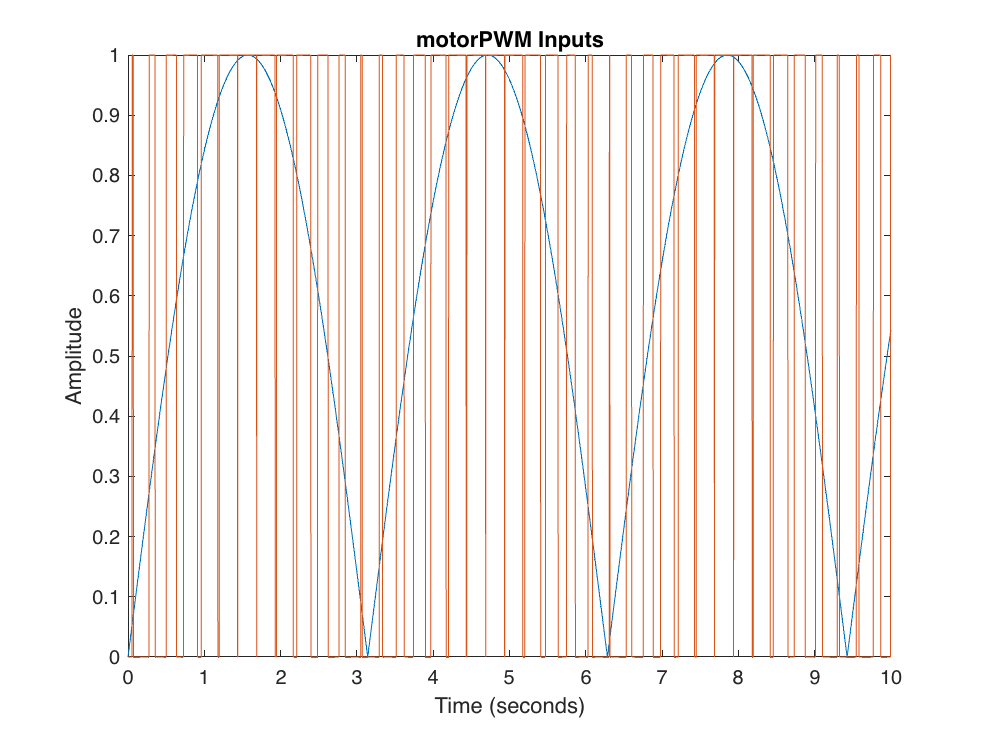

open_system('motorPWM')         % Load the model 
PWMout = sim('motorPWM');
figure                          % Create input figure
plot(PWMout.inputs)
title('motorPWM Inputs')
ylabel('Amplitude')

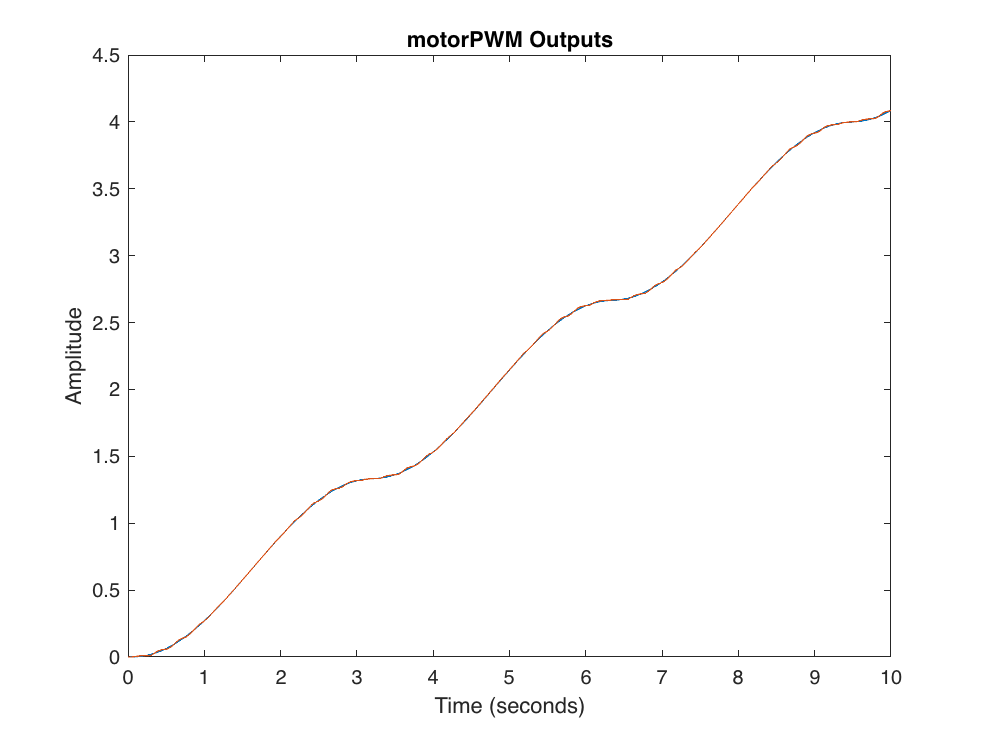

figure                          % Create output figure
plot(PWMout.outputs)
title('motorPWM Outputs')
ylabel('Amplitude')

#### Motor Response with Quantized Input

Shows the effect of a quantized input

*Requires motorQuantized.slx*

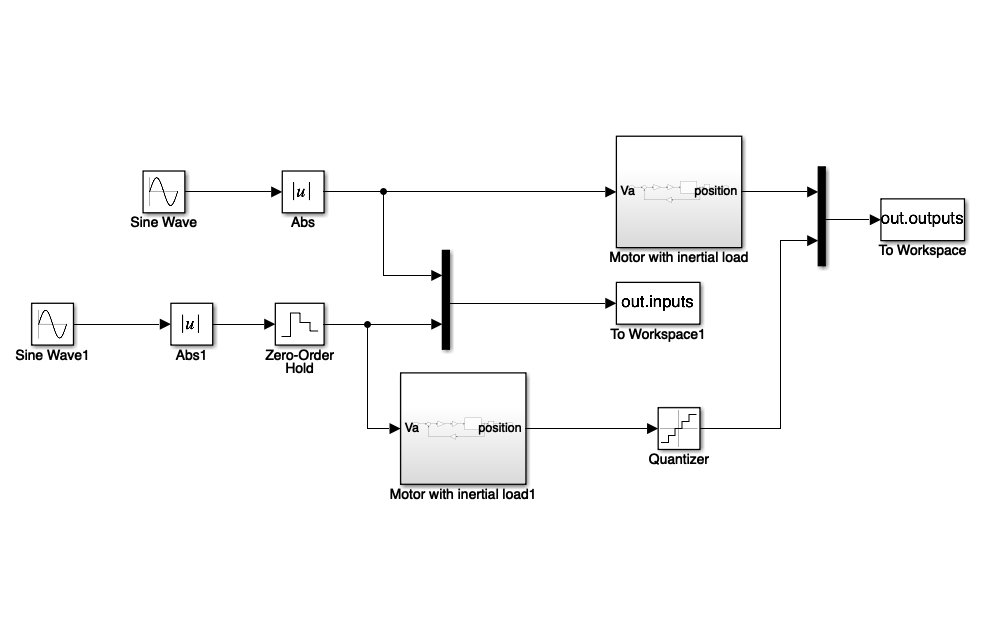

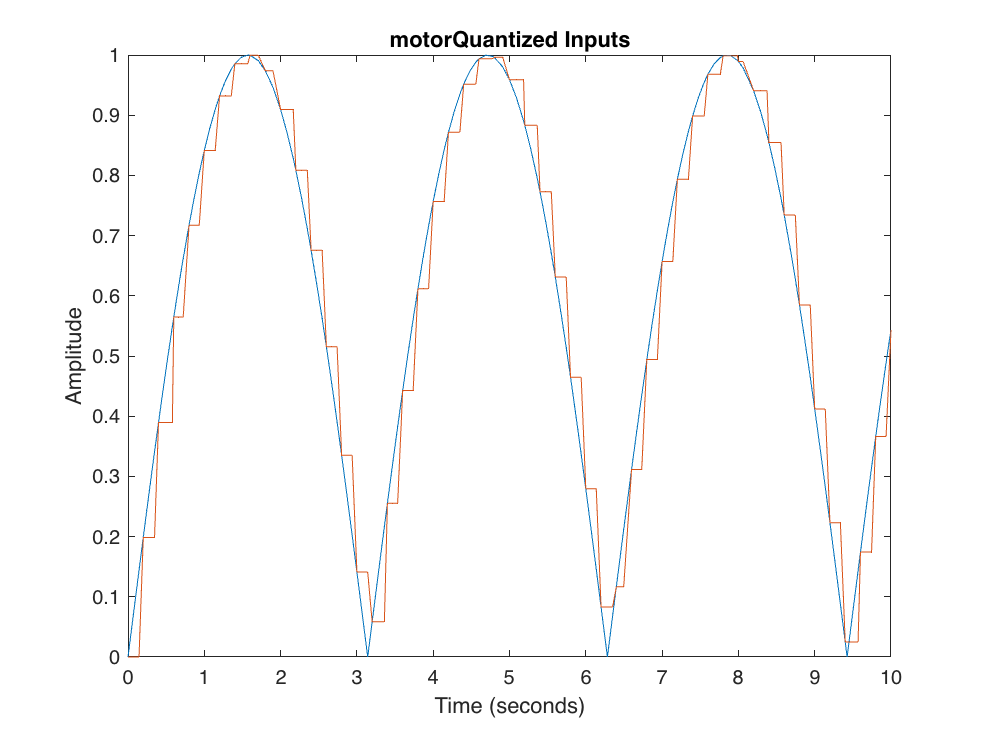

open_system('motorQuantized')   % Load the model
Qout = sim('motorQuantized');
figure                          % Create input figure
plot(Qout.inputs)
title('motorQuantized Inputs')
ylabel('Amplitude')

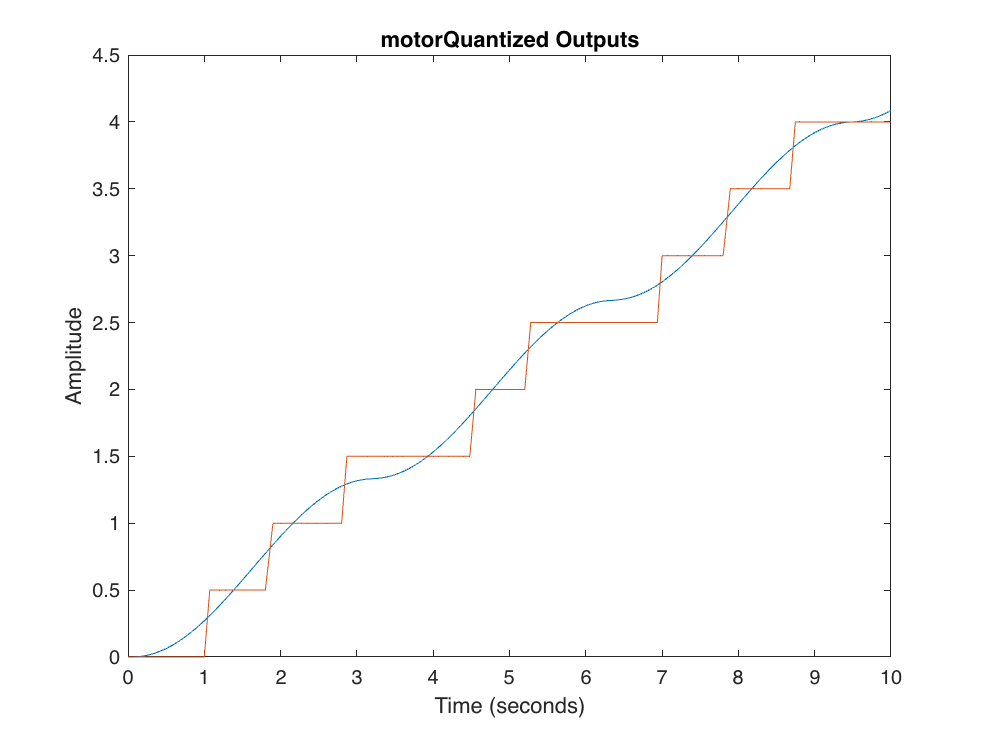

figure                          % Create output figure
plot(Qout.outputs)
title('motorQuantized Outputs')
ylabel('Amplitude')

A quantized input is an approximation of the continuous input, and although it requires fewer points, it isn't very useful.

#### Transfer Function of the Motor

Using slLinearizer and getIOTransfer, MATLAB will find the closed loop transfer function of the motor for me!

*Requires motor.slx*

motor is the "Motor" subsystem

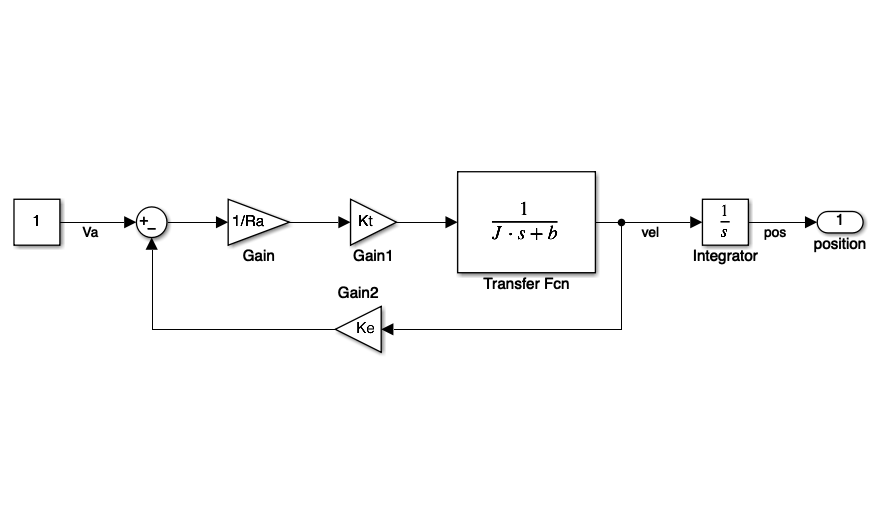

open_system('motor');                   % Load the model
sllin = slLinearizer('motor');          % Create new a slLinearizer model
addPoint(sllin,{'Va','pos','vel'});     % Label the reference input & block output
posTF = getIOTransfer(sllin,'Va','pos');% Use getIOTransfer to find TF of Pos/Va
velTF = getIOTransfer(sllin,'Va','vel');% Use getIOTransfer to find TF of Vel/Va

Turn the generated position transfer function into a coefficient array for use in Simulink.

posTF = tf(posTF)                       % Convert to a TF object

posTF =
 
  From input "Va" to output "pos":
      10
  ----------
  s^2 + 15 s
 
Continuous-time transfer function.



posNum = posTF.Numerator;               % Find the numerator coefficients
posNum = posNum{1};                     % Convert the numerator to a the right form
posDen = posTF.Denominator;             % Find the denominator coefficients
posDen = posDen{1};                     % Convert the denominator to a the right form

Turn the generated velocity transfer function into a coefficient array for use in Simulink.

velTF = tf(velTF)                       % Convert to a TF object

velTF =
 
  From input "Va" to output "vel":
    10
  ------
  s + 15
 
Continuous-time transfer function.



velNum = velTF.Numerator;               % Find the numerator coefficients
velNum = velNum{1};                     % Convert the numerator to a the right form
velDen = velTF.Denominator;             % Find the denominator coefficients
velDen = velDen{1};                     % Convert the denominator to a the right form

#### Motor Vs. Transfer Function - Position and Velocity

*Requires motorWithTF.slx*

Compares the generated transfer function with the baseline motor response.

(Red is the transfer function response, blue is the motor response)

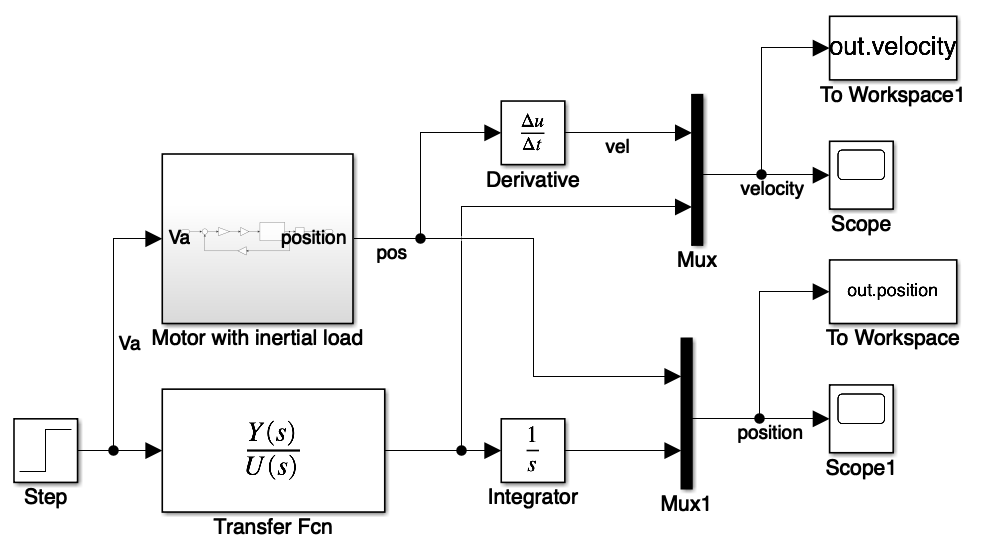

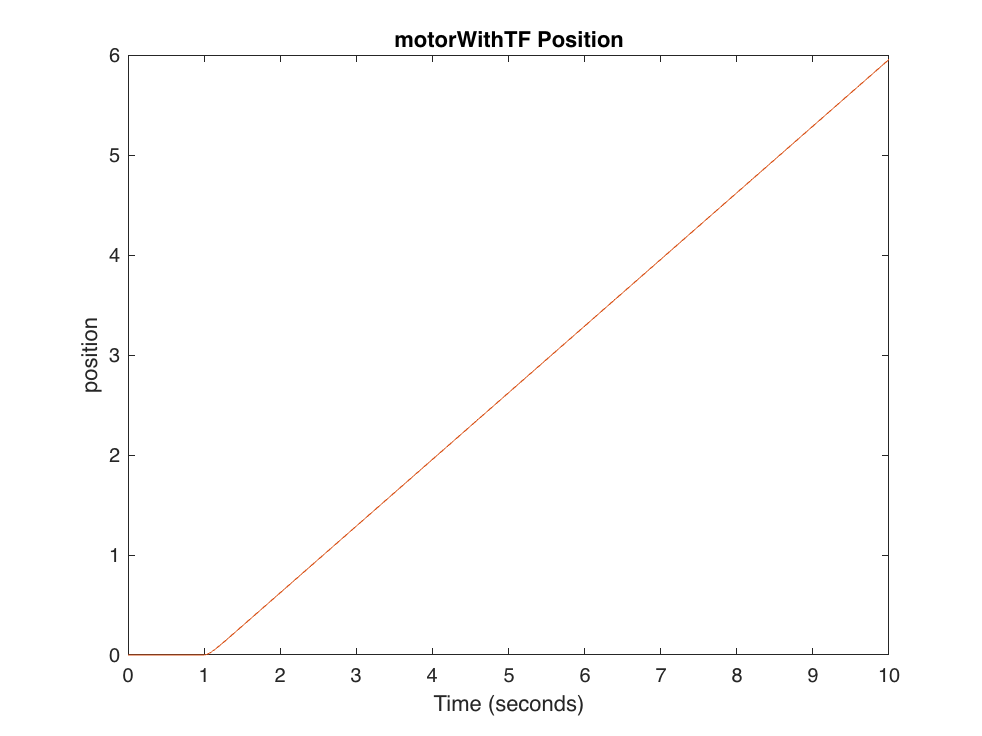

open_system('motorWithTF')              % Load the model
motorAndTFout = sim('motorWithTF');
figure                                  % Create the position figure 
plot(motorAndTFout.position)
title('motorWithTF Position')

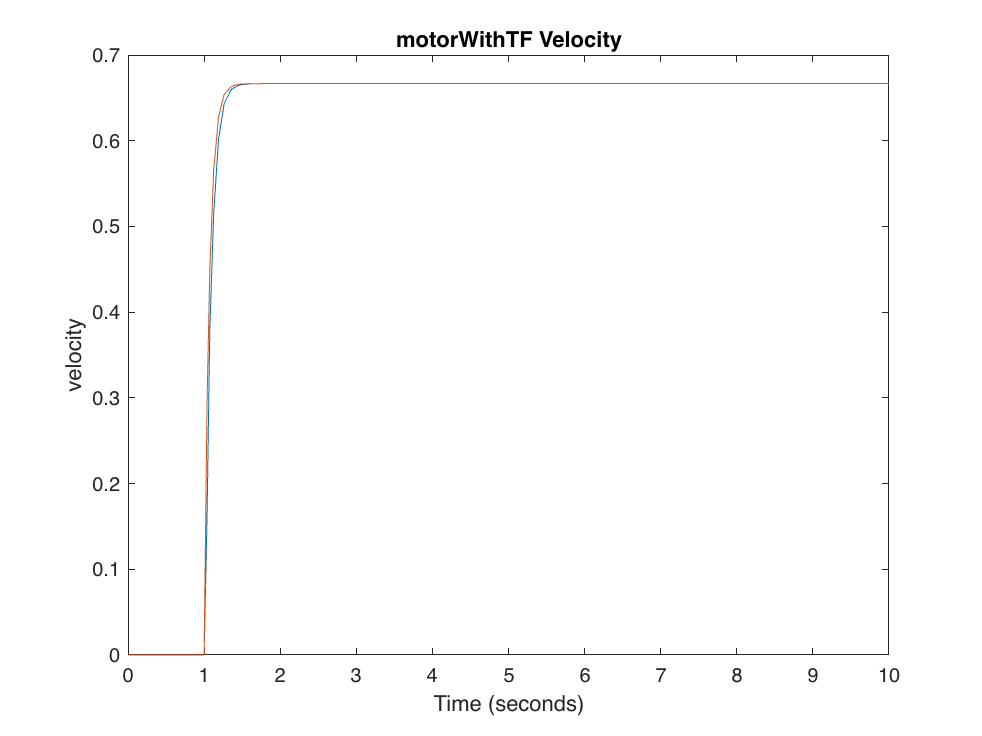

figure                                  % Create the velocity figure
plot(motorAndTFout.velocity)
title('motorWithTF Velocity')

#### Creating and Tuning a PI controller for Motor

Why open pidTuner in a new window when I can do it inline

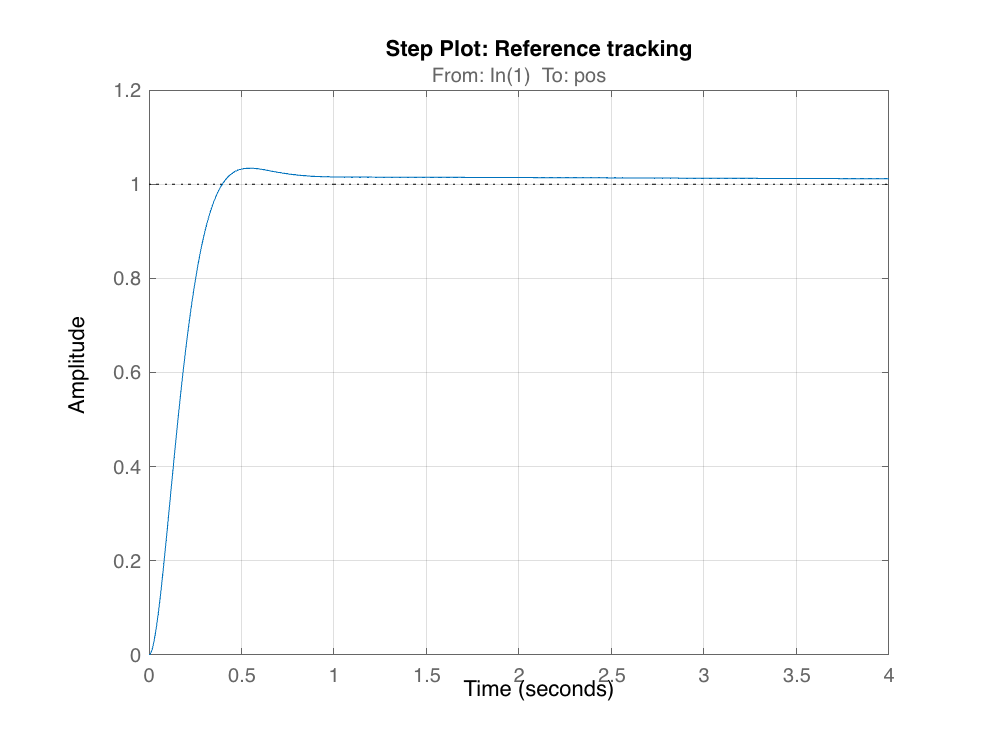

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/0.354509;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM = 100*0.781832;

% Define options for pidtune command
opts = pidtuneOptions('PhaseMargin',PM);

% PID tuning algorithm for linear plant model
[CI,pidInfo] = pidtune(posTF,'PI',wc,opts);

% Clear Temporary Variables
clear wc PM opts

% Get desired loop response
Response = getPIDLoopResponse(CI,posTF,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Display system response characteristics
disp(stepinfo(Response))

         RiseTime: 0.2487
    TransientTime: 0.7862
     SettlingTime: 0.7862
      SettlingMin: 0.9006
      SettlingMax: 1.0339
        Overshoot: 3.3931
       Undershoot: 0
             Peak: 1.0339
         PeakTime: 0.5440




% Clear Temporary Variables
clear Response
Kp = CI.Kp          % Displays the proportial coeficcient

Kp = 9.0398

Ki = CI.Ki          % Displays the integral coeficcient

Ki = 0.8926

#### PI Controled Motor Vs. Transfer Function - Position

The two lines occupy the exact same space on the plot which indicates the generated transfer function is correct.

*Requires TFLoopPI.slx and motorLoopPI.slx*

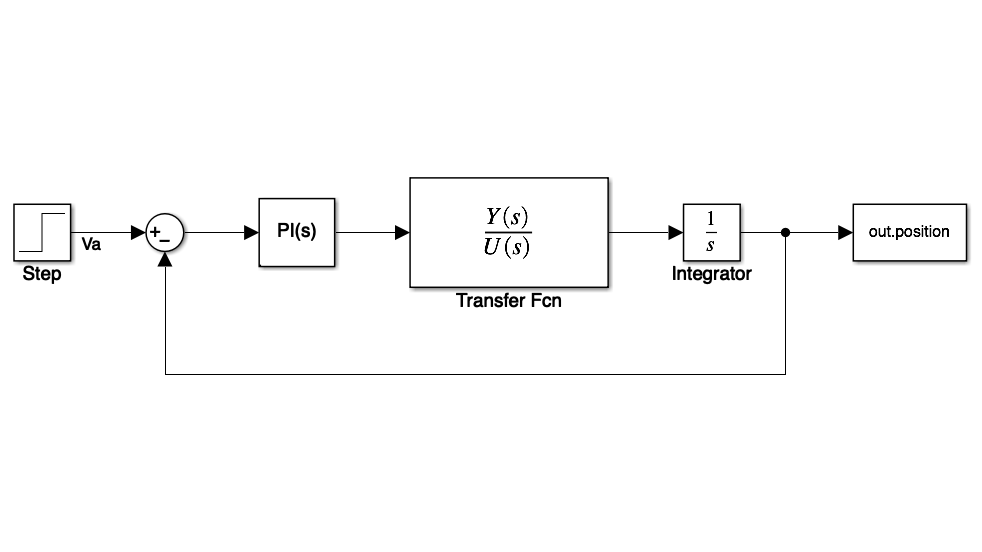

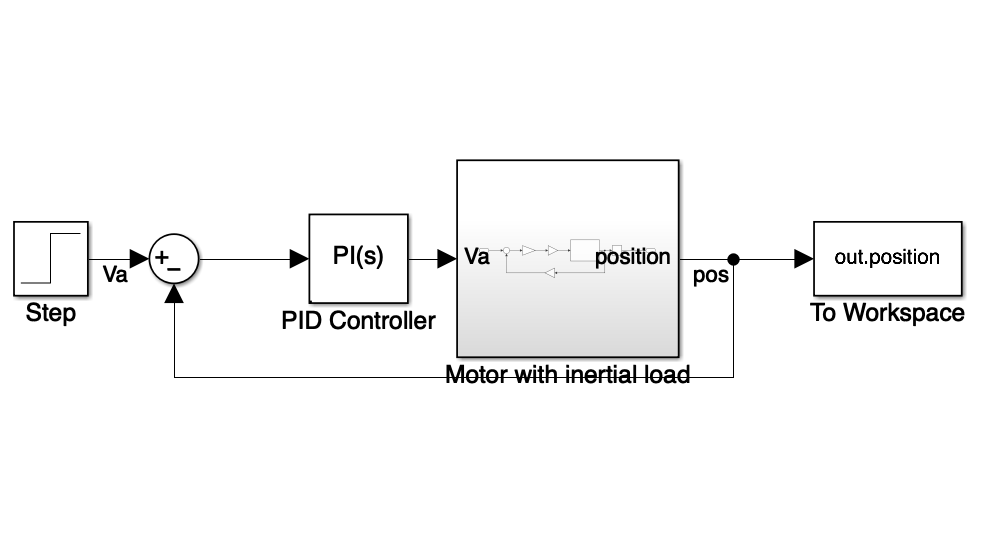

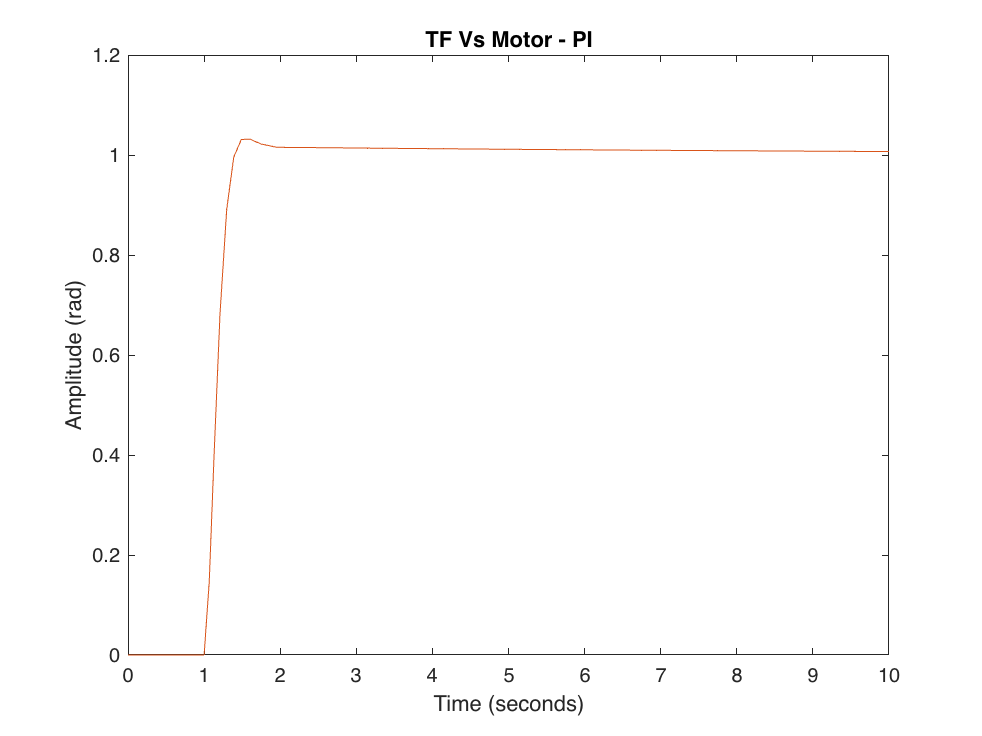

open_system('TFLoopPI')                 % Load the PI controlled TF model
open_system('motorLoopPI')              % Load the PI controlled motor model
tfOut = sim('TFLoopPI');
motorOut = sim('motorLoopPI');
figure                                  % Create the position figure
plot(tfOut.position)
hold on
plot(motorOut.position)
hold off
title('TF Vs Motor - PI')
ylabel('Amplitude (rad)')

#### Tuning a PD Controller for Motor

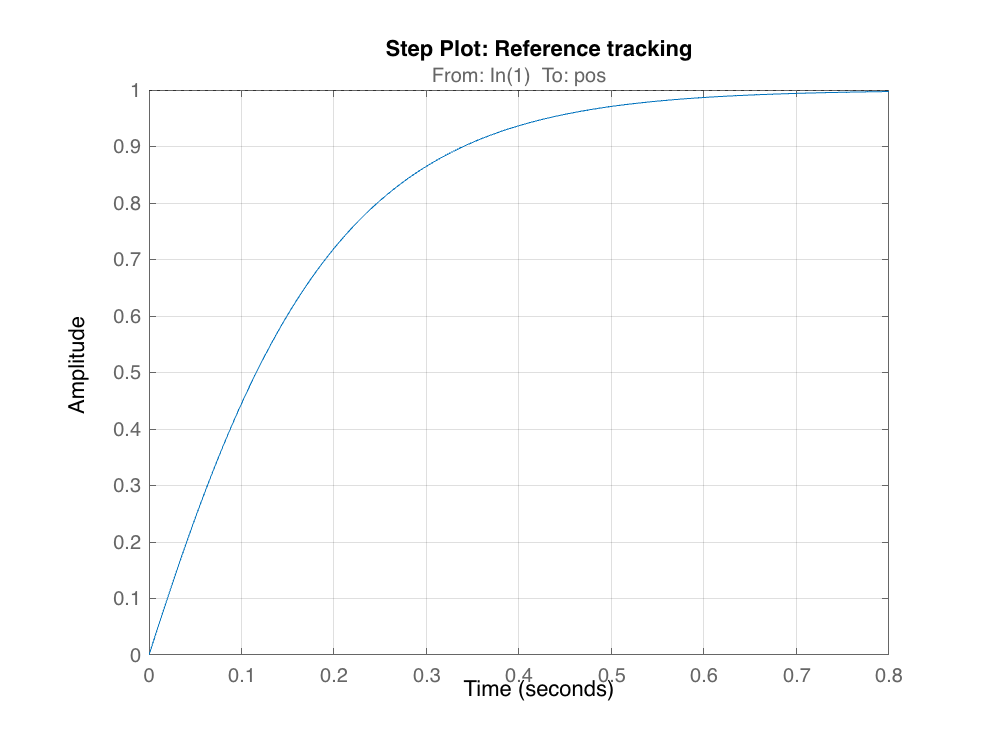

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc2 = 2/0.317841;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM2 = 100*0.855655;

% Define options for pidtune command
opts2 = pidtuneOptions('PhaseMargin',PM2);

% PID tuning algorithm for linear plant model
[CD,pidInfo2] = pidtune(posTF,'PD',wc2,opts2);

% Clear Temporary Variables
clear wc2 PM2 opts2

% Get desired loop response
Response2 = getPIDLoopResponse(CD,posTF,'closed-loop');

% Plot the result
stepplot(Response2)
title('Step Plot: Reference tracking')
grid on


% Display system response characteristics
disp(stepinfo(Response2))

         RiseTime: 0.3200
    TransientTime: 0.5478
     SettlingTime: 0.5478
      SettlingMin: 0.9021
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 0.9652




% Clear Temporary Variables
clear Response2
Kp = CD.Kp          % Displays the proportial coeficcient

Kp = 9.7166

Kd = CD.Kd          % Displays the derivative coeficcient

Kd = 0.5114

#### PD Controlled Motor Vs. Transfer Function - Position

*Requires TFLoopPD.slx and motorLoopPD.slx*

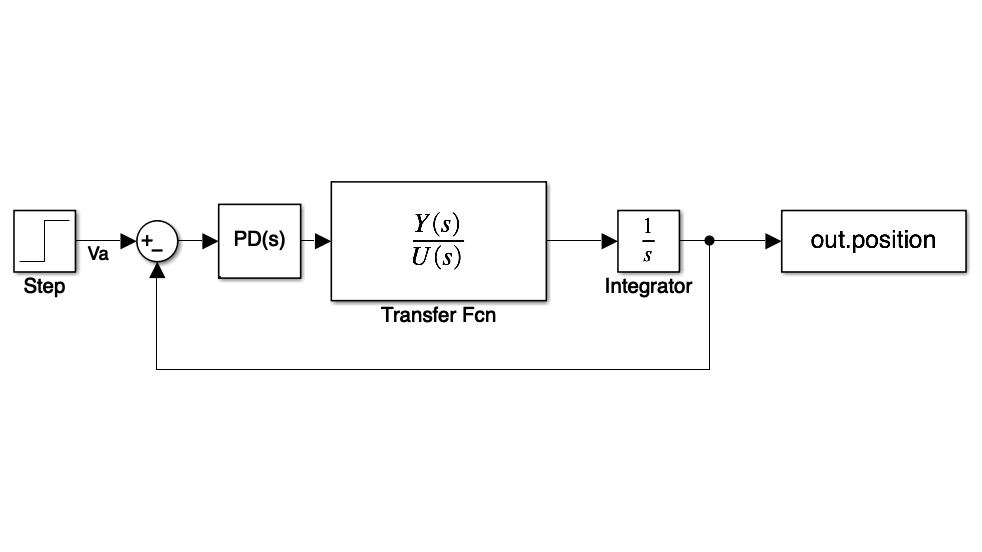

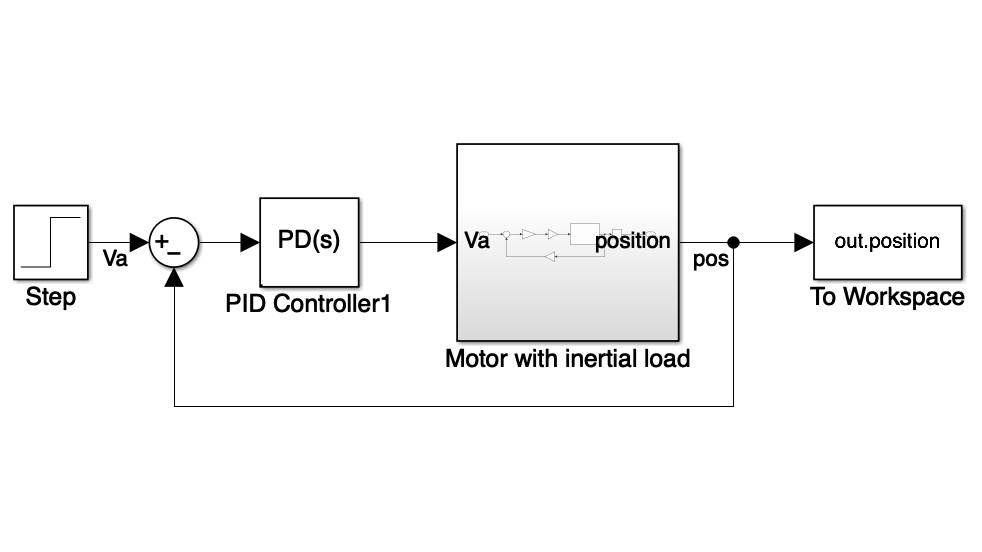

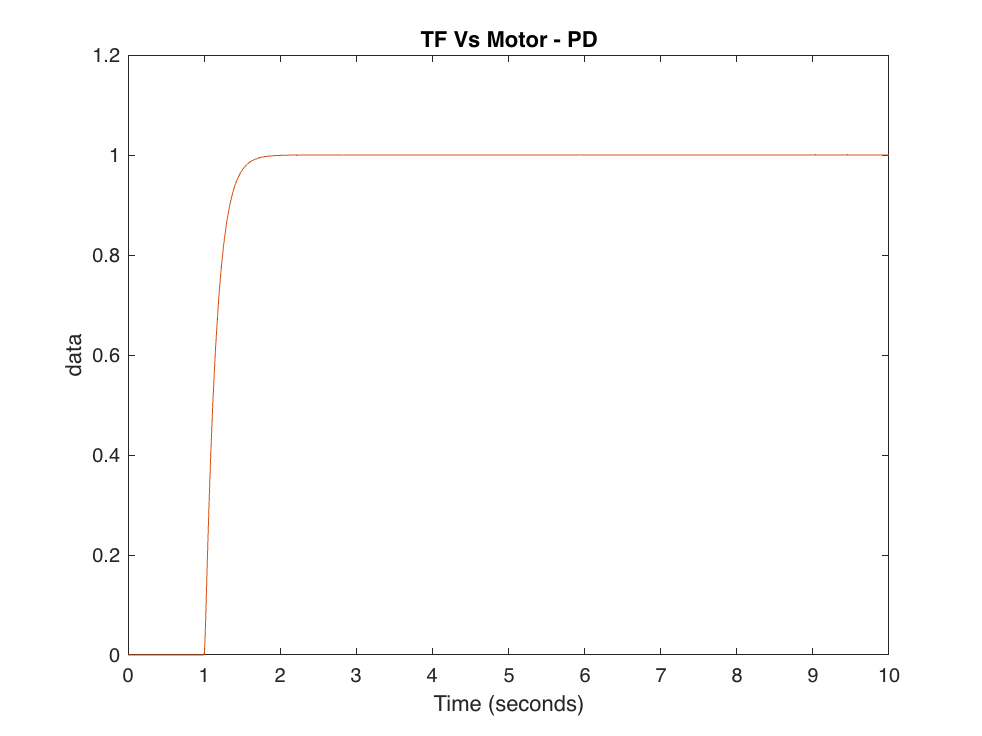

open_system('TFLoopPD')
open_system('motorLoopPD')
tfOut = sim('TFLoopPD');
motorOut = sim('motorLoopPD');
figure
plot(tfOut.position)
hold on
plot(motorOut.position)
hold off
title('TF Vs Motor - PD')